%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01; % secs
t = 0 : t_step : t_end

t =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


load('rmss_4.mat')
reps = 2;
Qs = logspace(5, 7, 7);
Ts = linspace(10e-3, 50e-3, 7);
taus = logspace(log10(0.5e-5), log10(2e-4), 8);

L_Qs = length(Qs);
L_Ts = length(Ts);

avg_rmss = mean(rmss, 1);
std_rmss = std(rmss, 1);
avg_std = mean(std_rmss, 'all')

avg_std = 62.2350


%avg_lins_rms = mean(linspace_rms, 1);

best_taus = zeros(L_Qs, L_Ts);

for j = 1 : L_Qs
    Q_orig = Qs(j);
    %lins_rms = avg_lins_rms(1, j);
    
    for k = 1 : L_Ts
        T = Ts(k);
        
        [min_rms, min_index] = min(rmss(1,j,k,:));
        min_rms;
        best_taus(j, k) = taus(min_index);
        
        for m = 1 : size(rmss, 4)
            %tau = taus(m)
            %avg_rmss(1, j, k, m)
        end
    end
end

best_taus

best_taus = 	1.0e+-3 *

    0.2000    0.2000    0.2000    0.2000    0.2000
    0.1181    0.2000    0.2000    0.2000    0.2000
    0.0143    0.0143    0.0143    0.0143    0.0143
    0.0143    0.0243    0.0243    0.0243    0.0243
    0.0697    0.0697    0.0697    0.0697    0.0697


reps = 10

reps = 10


best_rmss = zeros(reps, L_Ts, L_Ts);

tic
done = 0;
num_runs = reps * L_Qs * L_Ts

num_runs = 250


for l = 1 : reps
    f_axion = generate_axion_frequency_maxwellian(t, f_sampling, t_coherence, f_a, axion_linewidth);
    signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q);
    noise = generate_thermal_noise(t);
    
    for j = 1 : L_Qs
        Q_orig = Qs(j);
        Q = Q_orig / heterodyning_ratio;
        
        band_width = f_a / Q; % or f_a_original / Q_orig
        limiting_band = [f_a-band_width, f_a+band_width];
        
        %linspace_gives_rms = rms(f_axion - linspace(limiting_band(1), limiting_band(2), length(t)));
        %linspace_rms(l, j) = linspace_gives_rms;
        
        signal_Qed = signal * sqrt(Q_orig);
        
        parfor k = 1 : L_Ts % par here
            T = Ts(k);
            
            noise_power = calculate_noise_power(f_sampling, T);
            noise_Ted = noise * sqrt(noise_power);
            
            tau = best_taus(j, k);
    
            f_iwave = do_iwave_and_resonator(t, noise_Ted, signal_Qed, f_a, band_width, f_sampling, limiting_band, tau)
    
            % front to chop off
            start_secs = 0.0015;
            assert(start_secs < t(end)/3);
            start = round(start_secs * f_sampling);
            the_rms = rms(f_iwave(start:end) - f_axion(start:end));
            best_rmss(l, j, k) = the_rms;
            
            %figure
            %plot(t, f_axion - f_a)
            %hold on
            %plot(t, f_iwave - f_a)
        end
        done = done + L_Ts;
        frac_done = done/num_runs;
        timer_elapsed = toc;
        time_total = timer_elapsed / frac_done;
        time_remaining = time_total - timer_elapsed;
        fprintf('done %d%%, %d min gone, %d min rem\n', round(100*frac_done), round(timer_elapsed/60), round(time_remaining/60))
    end
end

done 2%, 0 min gone, 17 min rem
done 4%, 1 min gone, 17 min rem
done 6%, 1 min gone, 16 min rem
done 8%, 1 min gone, 16 min rem
done 10%, 2 min gone, 15 min rem
done 12%, 2 min gone, 15 min rem
done 14%, 2 min gone, 15 min rem
done 16%, 3 min gone, 14 min rem
done 18%, 3 min gone, 14 min rem
done 20%, 3 min gone, 14 min rem
done 22%, 4 min gone, 13 min rem
done 24%, 4 min gone, 13 min rem
done 26%, 4 min gone, 13 min rem
done 28%, 5 min gone, 12 min rem
done 30%, 5 min gone, 12 min rem
done 32%, 6 min gone, 12 min rem
done 34%, 6 min gone, 11 min rem
done 36%, 6 min gone, 11 min rem
done 38%, 7 min gone, 11 min rem
done 40%, 7 min gone, 10 min rem
done 42%, 7 min gone, 10 min rem
done 44%, 8 min gone, 10 min rem
done 46%, 8 min gone, 9 min rem
done 48%, 8 min gone, 9 min rem
done 50%, 9 min gone, 9 min rem
done 52%, 9 min gone, 8 min rem
done 54%, 9 min gone, 8 min rem
done 56%, 10 min gone, 8 min rem
done 58%, 10 min gone, 7 min rem
done 60%, 10 min gone, 7 min rem
done 62%, 11 min go

num = L_Qs * L_Ts;
Q_for_plot = zeros(1, num);
T_for_plot = zeros(1, num);
rms_for_plot = zeros(1, num);

best_rms_mean = mean(best_rmss, 1);

count = 0;
 
for j = 1 : L_Qs
    Q = Qs(j)
    
    for k = 1 : L_Ts
        count = count + 1;
        
        T = Ts(k);
        r = best_rms_mean(1, j, k);
        
        Q_for_plot(count) = Q;
        T_for_plot(count) = T;
        rms_for_plot(count) = r;
    end
end

Q = 100000

Q = 3.1623e+05

Q = 1000000

Q = 3.1623e+06

Q = 10000000

adstyle(8, 8)
%scatter(T_for_plot, Q_for_plot, 500, log(log(rms_for_plot)), 'filled')
%scatter(T_for_plot*1e3, Q_for_plot, 100000./log10(rms_for_plot).^5, rms_for_plot, 'filled')
scatter(T_for_plot*1e3, Q_for_plot, 800, rms_for_plot, 'filled')
%scatter(T_for_plot, Q_for_plot, 200000./rms_for_plot, rms_for_plot, 'filled')
set(gca, 'yscale','log', 'colorscale','log')
axis('padded')
c = colorbar('Ticks', [5e2 1e3 2e3 4e3]);
ylabel(c, 'RMS (Hz)')

%map = [1*linspace(0, 1, 500).^.3' 0.38*linspace(0, 1, 500).^.3' (1 - linspace(0, 0.2, 500).^.3)']
%map(end,:)

% colorbar - need to find where there is no match - ie if you draw a line
% right through the middle, and that should be the end of the color scale
% p = bone in command window
pink_alt = p(1:end*0.8,:);

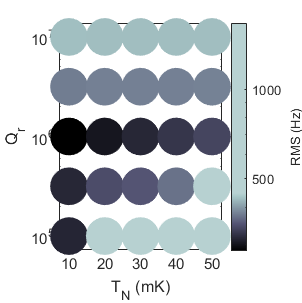

map = [pink_alt; repmat(pink_alt(end,:), 600, 1)];

colormap(map)
box('on')
xlabel('T_N (mK)')
ylabel('Q_r')

%saveas(gca, 'figures/quality_of_lock.eps', 'epsc');